# First Order Ordinary Linear Systems

In this section, we try to solve $\mathbf{A}_1\mathbf{u}'(x)+\mathbf{A}_0\mathbf{u}(x)=\mathbf{f}(x)$ for $x\in[a,b]$ w.r.t Dirichlet boundary conditions $\mathbf{u}(x)=\mathbf{g}(x)$ for $x\in\{a,b\}$ where $\mathbf{A}_i\in\mathbb{R}^{m\times m}$ and $\mathbf{u},\mathbf{f},\mathbf{g}\in\mathbb{R}^{m\times 1}$. For ellpticity, we require $\mathrm{det}(\mathbf{A}_1)\neq0$. We approximate the solution with $C^0$ Lagrange elment $\mathrm{CG}_q$ where we first try $q=1$(linear elements). The degrees of freedom are given by evaluating the basis at both ends of the interval. In element $K$ where $K=[v^K_1,v^K_2]$, the nodal bases are given by


$$\phi_1^K(x)\ =\ \frac{v^K_2-x}{l^K},$$



$$\phi_2^K(x)\ =\ \frac{x-v^K_1}{l^K},$$


where $l^K=v^K_2-v^K_1$. The solution ansatz is given as


$$\mathbf{u}(x)\approx\mathbf{u_C}(x)=\mathbf{C}\mathbf{\phi}(x)=\sum^n_{i=1}\mathbf{c}_i \cdot\phi_i(x),$$


where $\mathbf{c}_i$ is the $i_{th}$ column of $\mathbf{C}\in\mathbb{R}^{m\times n}$,  $\phi_i(x)$ is the global basis corresponding to the $i_{th}$ global degree of freedom (resp. the $i_{th}$ global vertex $v_i$ forming the discretized mesh). $\phi_i(x)$ for $i=1,n$ corresponds to the two boundary nodes $v_1=a$ and $v_n=b$.

We start by forming a 1D mesh $\mathcal{M}=\{K_i\}_{i=1}^{n-1}$ for the interval $\Omega=[a,b]$ and stores the global vertices in a 1D vector $\mathbf{v}=[v_1,\cdots,v_n]$ such that $K_i=[v_i\  ,\ v_{i+1}]$ for $i=1\cdots (n-1)$. 

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
f  = @(x) [1 ; 1] ;
g  = @(x) sin(x) + cos(x)    ;
ab = [ 0 , pi ] ;                 % ab = [ a , b ] domain

% Construct the model
model = Collocation1D(m, ab);
model.fitInterior(A1,A0,f,2)
model.fitBoundary([],@(x) [1,1],g,1)
model.fitTrueSol(u, Du)

% Discretization
n = 1000; %50 ;                         % n global vertices
model.linear_discretize(n)

We now try to evaluate the residuals. For a given point $x\in K_i$ with a local-to-global map $\iota_{K_i}(j)=i+(j-1)$ where $j=1,2$ we can evaluate the interior residuals

$R_{\Omega}(x)=\mathbf{A}_1\mathbf{u_C}'(x)+\mathbf{A}_2\mathbf{u_C}(x)-\mathbf{f}(x)
$,

namely,

$R_{\Omega}(x)=

\left[\matrix{\ 

(\phi_1^K)'\mathbf{A}_1+\phi_1^K\mathbf{A}_0

&,&  

(\phi_2^K)'\mathbf{A}_1+\phi_2^K\mathbf{A}_0

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)} } \right]-\mathbf{f}(x)$.

Similar for the boundary residuals with weights specified by the diagonal matrix $\Lambda\in\mathbb{R}^{m\times m}$

$R_{\Gamma}(x)=\Lambda[\mathbf{u_C}(x)-\mathbf{g}(x)]
$,

there is 


$$R_{\Gamma}(x)=\left[\matrix{\ \phi_1^K(x)\Lambda &,&  \phi_2^K(x)\Lambda\    } \right]\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)} } \right]-\Lambda\mathbf{g}(x)$$


Note if we write 

$\mathbf{B}^K_\Omega(x) = \left[\matrix{ (\phi_1^K)'\mathbf{A}_1+\phi_1^K\mathbf{A}_0 &,&  (\phi_2^K)'\mathbf{A}_1+\phi_2^K\mathbf{A}_0\    } \right]\in\mathbb{R}^{m\times 2m}$ for $x\in\mathrm{int}(\Omega)$, 

$\mathbf{B}^K_\Gamma(x) = \left[\matrix{\ \phi_1^K(x)\Lambda &,&  \phi_2^K(x)\Lambda\    } \right]\in\mathbb{R}^{m\times 2m}$ for $x\in \Gamma=\partial\Omega$, 

a single point $x$ will generate $m$ lines in the final assembled system $\mathbf{B}\mathbf{c}=\mathbf{d}$ where 

$\mathbf{B}=\left[\matrix{ \mathbf{B}_\Omega  \cr  \mathbf{B}_\Gamma} \right]$ , $\mathbf{c}=\mathrm{vec}(\mathbf{C})=\left[\matrix{ \mathbf{c}_1  \cr  \vdots\cr\mathbf{c}_n} \right]$ , $\mathbf{d}=\left[\matrix{ \mathbf{d}_\Omega  \cr  \mathbf{d}_\Gamma} \right]$

and if we define slice $\mathbf{s}(i)=im-m+1:im$, there is

$\mathbf{B}_{\Omega}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2)]\ ) := \mathbf{B}^K_\Omega(x_i)$,

$\mathbf{B}_{\Gamma}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2)]\ ) := \mathbf{B}^K_\Gamma(\hat{x}_i)$,

and 

$\mathbf{d}_{\Omega}(\ \mathbf{s}(i)\  ) := \mathbf{f}(x_i)$,

$\mathbf{d}_{\Gamma}(\ \mathbf{s}(i)\  ) := \Lambda\mathbf{g}(\hat{x}_i)$,

for sets of selected points $\{{x}_i\}_{i=1}^{N_{\Omega}}\subset \Omega$ and $\{{\hat{x}}_i\}_{i=1}^{ N_{\Gamma} } \subset \Gamma$, $N=N_{\Omega}+N_{\Gamma}$.

% Points Selection
rng(42) ;  % random seed
h = model.gm.Mesh.MinElementSize;
k = max([ceil(1/(pi*h)),5])  ; % 1000  % k*n interior points 
interior_points = linspace(ab(1), ab(2), k*n) ; % interior points
boundary_points = ab ; % boundary points

% System assemble
Lambda = diag(h.^(-3/2)*ones(1,1)) ;       % square(weights) for BC
[B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(interior_points) ;
[B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(boundary_points, Lambda) ;
B = [B_Omega ; B_Gamma] ; d = [d_Omega ; d_Gamma];

% figure()
% SHM=SHeatmap(full([B_Omega;B_Gamma]),'Format','sq');
% SHM=SHM.draw();

@author : slandarer


% colormap(flipud(slanCM(96)));

@author : slandarer


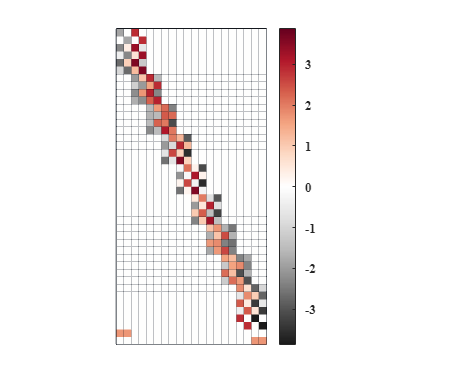

% SHM.setBox('Color',[0,8,20]./255)
% set(gca, 'XTick', []);
% set(gca, 'YTick', []);
% colorbar_handle = colorbar;
% colorbar_handle.FontWeight = 'bold';

We first solve the assembled matrix directly

% addpath('./Skechers/');
% load('./data/1DsktSample/1DsktSampleModel_small.mat');
% B = [model.Omega_assemble.B ; model.Gamma_assemble.B]; 
% d = [model.Omega_assemble.d ; model.Gamma_assemble.d];

c = B\d ; model.C = model.reshape2mat(c); 
X = linspace(model.Omega(1), model.Omega(2), 100) ;
u_fit = model.evaluate_LSFEM(X) ;
u_true = model.u(X) ;
% save('./data/1DsktSample/1DsktSampleModel_small.mat', 'model');

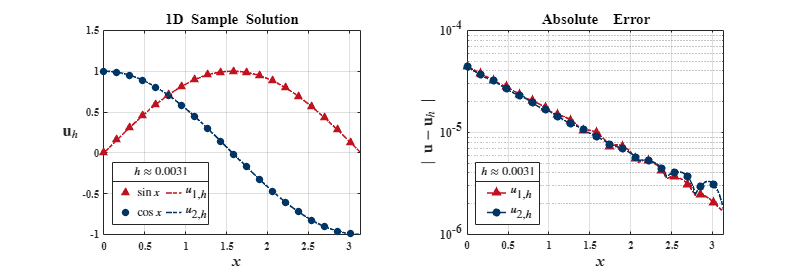

% Plot Result
color = [193/255,  18/255, 31/255; 
         0/255,  53/255, 102/255;];

figure; set(gcf,'position',[0, 0, 1000, 350]); 
f = tiledlayout(1,2); 

nexttile(1);
scatter( X(1:5:100), u_true(1,1:5:100), 'Marker', '^', 'LineWidth', 1, ...
        'MarkerEdgeColor', color(1,:), 'MarkerFaceColor', color(1,:), ...
        'MarkerFaceAlpha', 1, 'DisplayName', '$\sin{x}$'); 
hold on; grid on; box on;
scatter( X(1:5:100), u_true(2,1:5:100), 'Marker', 'o', 'LineWidth', 1, ...
        'MarkerEdgeColor', color(2,:), 'MarkerFaceColor', color(2,:), ...
        'MarkerFaceAlpha', 1, 'DisplayName', '$\cos{x}$');
plot( X, u_fit(1,:), 'LineStyle', '-.', 'LineWidth', 1.5, 'Color', color(1,:), 'DisplayName', '$u_{1,h}$'); 
plot( X, u_fit(2,:), 'LineStyle', '-.', 'LineWidth', 1.5, 'Color', color(2,:), 'DisplayName', '$u_{2,h}$');

set(gca,'fontname','times','FontWeight','Bold'); ax = gca; 
ax.XAxis.FontSize = 10; xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ax.YAxis.FontSize = 10; ylabel("${\mathbf{u}_h}$",'FontSize', 15, 'Rotation', 360, 'Interpreter', 'latex');  
title({'1D  Sample  Solution'},'fontweight','bold','FontSize',14)

lgd = legend('FontSize', 10, 'Interpreter', 'latex', 'Location','southwest'); lgd.ItemTokenSize = [15, 10]; lgd.NumColumns = 2;
title(lgd,{'$h\approx0.0031$'},'FontSize',10);
lgd.Position(2) = lgd.Position(2) ; 
lgd.Position(3) = lgd.Position(3) + 0.01; 
lgd.Position(4) = lgd.Position(4) + 0.06;
 

nexttile(2);
abs_error = abs(u_fit - u_true);
semilogy( X, abs_error(1,:), '-.', 'LineWidth', 1.5, 'Marker', '^', 'MarkerFaceColor', color(1,:),...
         'MarkerIndices', 1:5:100, 'Color', color(1,:), 'DisplayName', '$u_{1,h}$'); 
hold on; grid on; box on;
semilogy( X, abs_error(2,:), '-.', 'LineWidth', 1.5, 'Marker', 'o', 'MarkerFaceColor', color(2,:),...
         'MarkerIndices', 1:5:100, 'Color', color(2,:), 'DisplayName', '$u_{2,h}$');

set(gca,'fontname','times','FontWeight','Bold'); ax = gca; 
ax.XAxis.FontSize = 10; xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ax.YAxis.FontSize = 10; ylabel("$\left|\ \mathbf{u}-{\mathbf{u}_h}\ \right|$",'FontSize', 15, 'Interpreter', 'latex');  
title({'Absolute    Error'},'fontweight','bold','FontSize',14)

lgd = legend('FontSize', 10, 'Interpreter', 'latex', 'Location','southwest'); lgd.ItemTokenSize = [19, 10]; lgd.NumColumns = 1;
title(lgd,{'$h\approx0.0031$'},'FontSize',10);
lgd.Position(2) = lgd.Position(2); 
lgd.Position(3) = lgd.Position(3) + 0.01; 
lgd.Position(4) = lgd.Position(4) + 0.06;

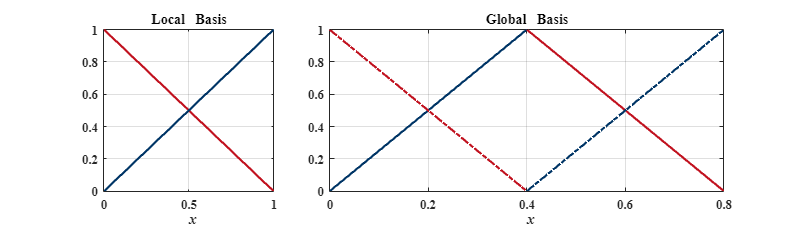

 % Plot Basis
color = [193/255,  18/255, 31/255; 
         0/255,  53/255, 102/255;];

figure; set(gcf,'position',[0, 0, 1000, 300]); tiledlayout(1,3); 
nexttile(1);
plot( 0:1, [1,0], '-', 'LineWidth', 2, 'Color', color(1,:), 'DisplayName', '$\phi^K_1$'); 
hold on; grid on; box on;
plot( 0:1, [0,1], '-', 'LineWidth', 2, 'Color', color(2,:), 'DisplayName', '$\phi^K_2$');
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
title({'Local   Basis'},'fontweight','bold','FontSize',14)
set(gca,'fontname','times','FontWeight','Bold');
xticklabel = get(gca,'XTickLabel'); set(gca, 'XTickLabel', xticklabel, 'FontName', 'Times New Roman', 'fontsize', 12);
 
nexttile(2, [1, 2]);
plot( 0:1, [0,1], '-', 'LineWidth', 2, 'Color', color(2,:));
hold on; grid on; box on;
plot( 1:2, [1,0], '-', 'LineWidth', 2, 'Color', color(1,:));
plot( 0:1, [1,0], '-.', 'LineWidth', 2, 'Color', color(1,:));
plot( 1:2, [0,1], '-.', 'LineWidth', 2, 'Color', color(2,:));
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
title({'Global   Basis'},'fontweight','bold','FontSize',14)
set(gca,'fontname','times','FontWeight','Bold');
xticklabel = get(gca,'XTickLabel'); set(gca, 'XTickLabel', xticklabel, 'FontName', 'Times New Roman', 'fontsize', 12);